clc
close all
global H;
global TM;
global SIGMA;
global Q;
global D;
global stepsize

load slugdata.mat

D=60;
Q=50;
 
SIGMA=0.01*ones(size(H));

stepsize = [2e-5; 4e-2];

m0 = [5e-3;1]; 

N = 2e5; 
BURNIN = 1e4;
skip = 1000;

### 4.(a) Identify the number of samples that remain after the thinning process. Plot the hisstory of the thinned posterior samples, and include the true parameters.

[mout,mMAP,pacc]=mcmc('logprior','loglikelihood','generate','logproposal',m0,N)

mout =     0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049
    1.0000    0.9565    0.9565    0.9565    0.9565    0.9565    0.9401    0.9401    0.8967    0.8967    0.8967    0.8866    0.8715    0.8249    0.7757    0.7675    0.7675    0.7675    0.7533    0.7533    0.7040    0.7040    0.7040    0.6201    0.6326    0.6326    0.6289    0.6944    0.6880    0.6880    0.6880    0.6734    0.6195    0.6195    0.6195    0.6229    0.6229    0.6121    0.6121    0.6121    0.6121    0.6121    0.6428    0.6428    0.6882    0.6882    0.6882    0.7023    0.7023  

mMAP =     0.0021
    0.5853


pacc = 0.2976


%downsample results to reduce correlation
k=(BURNIN:skip:N);
mskip=mout(:,k);
disp(['The corresponding number of samples = ',num2str(length(mskip)),' samples']);

The corresponding number of samples = 191 samples


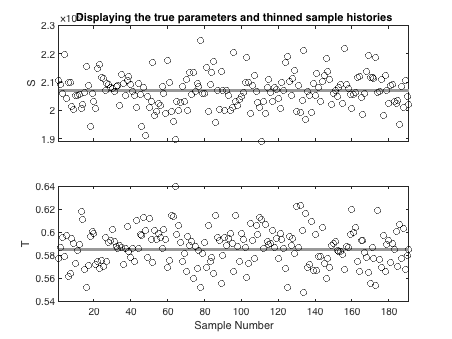


mtrue = [0.00207;0.585];

%plot parameter sample histories
figure(1)
clf
for i=1:2
  subplot(2,1,i)
  plot([1 length(mskip)],[mtrue(i) mtrue(i)],'Color',[0.6 0.6 0.6],'LineWidth',3);
  hold on
  plot(mskip(i,:),'ko')
  hold off
  if i~=2
    set(gca,'Xticklabel',[]);
  end
  xlim([1 length(mskip)])
end
xlabel('Sample Number')
subplot(2,1,1)
ylabel('S')
title('Displaying the true parameters and thinned sample histories')
subplot(2,1,2)
ylabel('T')

### b) Plot autocorrelations of S and T both before and after thinning. Discuss if there was enough thinning with skipping every 1000 samples.

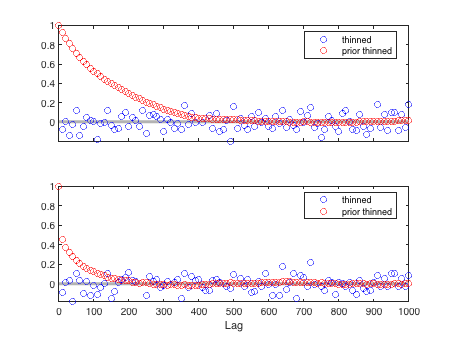

figure(2)
clf
laglen=1000;
lags=(-laglen:laglen)';
acorr=zeros(2*laglen+1,2);
aco=zeros(2*laglen+1,2);

for i=1:2
      aco(:,i)=calc_corr(mout(i,:)',laglen);
end

for i=1:2
  acorr(:,i)=calc_corr(mskip(i,:)',laglen);
  subplot(2,1,i);
  plot([0 laglen],[0 0],'Color',[0.7 0.7 0.7],'LineWidth',3); hold on
  plot(lags(laglen+1:10:laglen*2+1),acorr(laglen+1:10:laglen*2+1,i),'bo');
  plot(lags(laglen+1:10:laglen*2+1),aco(laglen+1:10:laglen*2+1,i),'ro');
  legend('','thinned', 'prior thinned',Location='best')
  hold off
  
  
  if i~=2
    set(gca,'Xticklabel',[]);
  end
end
xlabel('Lag')

### (c) Estimate the 95% credible intervals by sorting the ensemble of parameter estimates, as is done in Exercise 11.4.

% estimate the 95% credible intervals
for i=1:2
  msort=sort(mskip(i,:));
  m2_5(i) = msort(round(2.5/100*length(mskip)));
  m97_5(i) =  msort(round(97.5/100*length(mskip)));
  disp(['95% confidence interval for m', num2str(i),' is [', num2str(m2_5(i)),',', num2str(m97_5(i)),']'])
end

95% confidence interval for m1 is [0.0019431,0.0021946]
95% confidence interval for m2 is [0.55348,0.61766]


### (d) Estimate the Bayesian confidence intervals as we've done previously, using the standard deviation of the MCMC samples.

for i=1:2
  msort=sort(mskip(i,:)); 
  m97_5b = mMAP(i) + 1.96*std(msort);
  m2_5b =  mMAP(i) - 1.96*std(msort);
  disp(['95% confidence interval for m', num2str(i),' is [', num2str(m2_5b),',', num2str(m97_5b),']'])
end

95% confidence interval for m1 is [0.0019508,0.0021899]
95% confidence interval for m2 is [0.55388,0.61662]


### (e) As in Figure 11.16, plot the sampled posterior distribution S vs T with the true model as a large black dot, and the MAP estimate with an open circle. On the same graph plot the thinned samples as gray dots and 95% credible intervals by a box.

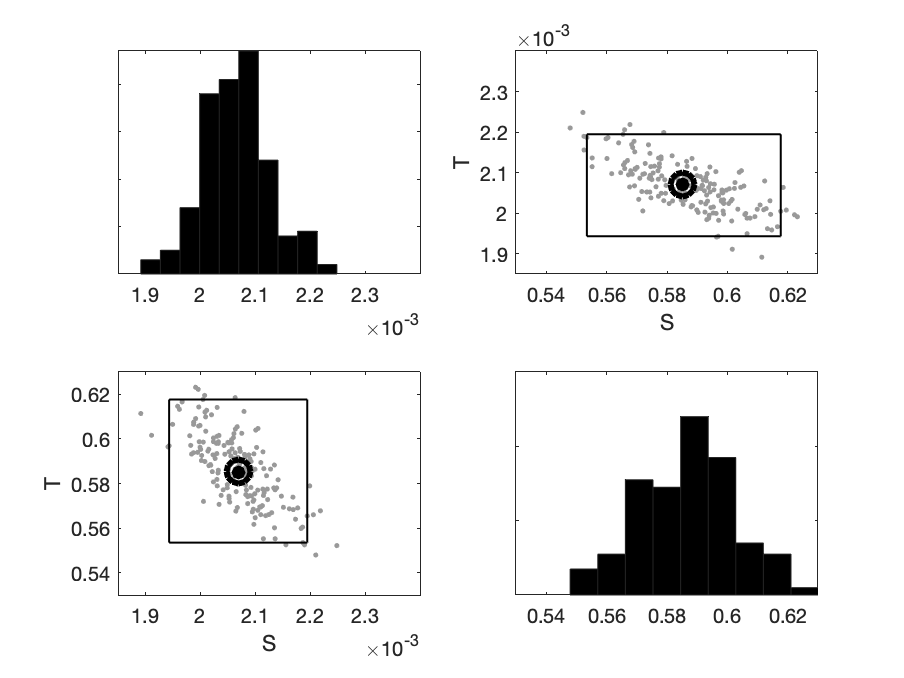

%plot a scatter plot and histogram of the posterior distribution
mlims=[0.00185 0.0024; 0.53 0.63];

figure(3)
clf
for i=1:2
  for j=1:2
    subplot(2,2,2*(i-1)+j)
    if i==j
      hist(mskip(i,:));
      h = findobj(gca,'Type','patch');
      set(h,'FaceColor','k')
      set(gca,'Yticklabel',[]);
      xlim(mlims(i,:));
    else
      plot(mskip(j,:),mskip(i,:),'k.','Markersize',6,'Color',[0.6 0.6 0.6]);
      hold on
      % plot the true answer as a large black dot
      plot(mtrue(j),mtrue(i),'k.','Markersize',24);
      % plot the accepted answers as gray dots
      plot(mMAP(j),mMAP(i),'ko','Markersize',12,'LineWidth',3);
      % plot the 95% ci as a box
      plot([m2_5(j),m97_5(j)],[m2_5(i),m2_5(i)],'k-','LineWidth',1);
      plot([m2_5(j),m97_5(j)],[m97_5(i),m97_5(i)],'k-','LineWidth',1);
      plot([m2_5(j),m2_5(j)],[m2_5(i),m97_5(i)],'k-','LineWidth',1);
      plot([m97_5(j),m97_5(j)],[m2_5(i),m97_5(i)],'k-','LineWidth',1);
      xlim(mlims(j,:));
      ylim(mlims(i,:));
      
      xlabel('S'); ylabel('T')
      
      hold off
    end
  end
end

### (f) Apply a Q-Q plot and discuss the normality of the sampled posterior distribution. In your discussion, address how the 95% credible intervals play a role.

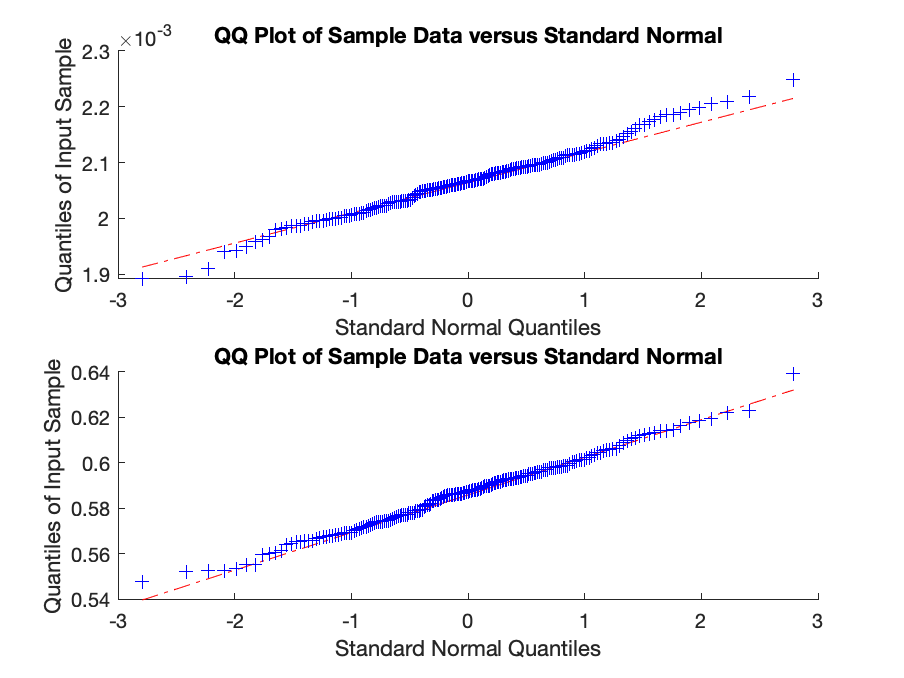

figure(4)

subplot(2,1,1)
qqplot(sort(mskip(1,:)))
ylabel('Quantiles of Input Sample');
xlabel('Standard Normal Quantiles');

subplot(2,1,2)
qqplot(sort(mskip(2,:)))
ylabel('Quantiles of Input Sample');
xlabel('Standard Normal Quantiles');